## 2.

### HashString()

N_values = [5e5,1e6,2e6];
imin = 6;
imax = 20;
letras = ['a':'z', 'A':'Z'];

hash_array = cell(1,length(N_values));
tempo_hashString = zeros(1,length(N_values));
fprintf('Colisões para hashString\n');

Colisões para hashString


col_array_hash = zeros(1,length(N_values));
max_hash = zeros(1,length(N_values));

for index = 1:length(N_values)
    tic
    N = N_values(index);
    cell = KeyGenerator(imin,imax,N,letras); 
    hashcode = zeros(1,N);

    for i = 1:N
        current = cell{i};
        hashcode(i)=rem(hashstring(current,N),N) + 1;
        
    end
   
    [~, ~, indices] = unique(hashcode);
    counter = accumarray(indices,1);

    colisoes_hash = sum(counter(counter > 1)) - length(counter(counter > 1));
    col_array_hash(index) = colisoes_hash;

    max_colision_hash = max(counter);
    max_hash(index) = max_colision_hash;

    fprintf(' N: %d\n  Número de colisões = %d\n  Máximo de atribuições = %d\n', N, colisoes_hash, max_colision_hash);

    hash_array{index} = hashcode;
    tempo_hashString(index) = toc;
    
end

 N: 500000
  Número de colisões = 222040
  Máximo de atribuições = 22
 N: 1000000
  Número de colisões = 447628
  Máximo de atribuições = 29
 N: 2000000
  Número de colisões = 895499
  Máximo de atribuições = 41


### DJB31MA()

N_values = [5e5,1e6,2e6];
imin = 6;
imax = 20;
letras = ['a':'z', 'A':'Z'];

hash_array_djb = cell(1,length(N_values));
tempo_DJB31MA = zeros(1,length(N_values));
fprintf('Colisões para DJB31MA\n');

Colisões para DJB31MA


col_array_DJB31MA = zeros(1,length(N_values));
max_DJB31MA = zeros(1,length(N_values));

for index = 1:length(N_values)
    tic
    N = N_values(index);
    cell = KeyGenerator(imin,imax,N,letras); 
    hashcode = zeros(1,N);

    for i = 1:N
        current = cell{i};
        hashcode(i)=rem(DJB31MA(current,N),N)+1;
    end

    [~, ~, indices] = unique(hashcode);
    counter = accumarray(indices,1);

    colisoes_DJB31MA = sum(counter(counter > 1)) - length(counter(counter > 1));
    col_array_DJB31MA(index) = colisoes_DJB31MA;

    max_colision_DJB31MA = max(counter);  
    max_DJB31MA(index) = max_colision_DJB31MA;

    fprintf(' N: %d\n Número de colisões = %d\n Máximo de atribuições = %d\n', N, colisoes_DJB31MA, max_colision_DJB31MA);

    hash_array_djb{index} = hashcode;
    tempo_DJB31MA(index) = toc;

end

 N: 500000
 Número de colisões = 184093
 Máximo de atribuições = 8
 N: 1000000
 Número de colisões = 367833
 Máximo de atribuições = 8
 N: 2000000
 Número de colisões = 735821
 Máximo de atribuições = 9


### String2Hash.m -> djb2

N_values = [5e5,1e6,2e6];
imin = 6;
imax = 20;
letras = ['a':'z', 'A':'Z'];

hash_array_str = cell(1,length(N_values));
tempo_DJB2 = zeros(1,length(N_values));
fprintf('Colisões para djb2\n');

Colisões para djb2


col_array_djb2 = zeros(1,length(N_values));
max_djb2 = zeros(1,length(N_values));

for index = 1:length(N_values)
    tic

    N = N_values(index);
    cell = KeyGenerator(imin,imax,N,letras); 
    hashcode = zeros(1,N);

    for i = 1:N
        current = cell{i};
        hashcode(i)=rem(string2hash(current,'djb2'),N)+1;
    end

    [~, ~, indices] = unique(hashcode);
    counter = accumarray(indices,1);

    colisoes_djb2 = sum(counter(counter > 1)) - length(counter(counter > 1));
    col_array_djb2(index) = colisoes_djb2;

    max_colision_djb2 = max(counter);  
    max_djb2(index) = max_colision_djb2;

    fprintf(' N: %d\n Número de colisões = %d\n Máximo de atribuições = %d\n', N, colisoes_djb2, max_colision_djb2);

    hash_array_str{index} = hashcode;
    tempo_DJB2(index) = toc;

end

 N: 500000
 Número de colisões = 183787
 Máximo de atribuições = 8
 N: 1000000
 Número de colisões = 367905
 Máximo de atribuições = 8
 N: 2000000
 Número de colisões = 735524
 Máximo de atribuições = 10


### String2Hash.m -> sdbm

N_values = [5e5,1e6,2e6];
imin = 6;
imax = 20;
letras = ['a':'z', 'A':'Z'];
tempo_SDBM = zeros(1,length(N_values));

hash_array_str_sb = cell(1,length(N_values));
fprintf('Colisões para sbdm\n');

Colisões para sbdm


col_array_sdbm = zeros(1,length(N_values));
max_sdbm = zeros(1,length(N_values));

for index = 1:length(N_values)
    tic
    N = N_values(index);
    cell = KeyGenerator(imin,imax,N,letras); 
    hashcode = zeros(1,N);

    for i = 1:N
        current = cell{i};
        hashcode(i)=rem(string2hash(current,'sdbm'),N)+1;
    end
     
    [~, ~, indices] = unique(hashcode);
    counter = accumarray(indices,1);

    colisoes_sdbm = sum(counter(counter > 1)) - length(counter(counter > 1));
    col_array_sdbm(index) = colisoes_sdbm;

    max_colision_sbdm = max(counter);  
    max_sdbm(index) = max_colision_sbdm;

    fprintf(' N: %d\n Número de colisões = %d\n Máximo de atribuições = %d\n', N, colisoes_sdbm, max_colision_sbdm);
    
    hash_array_str_sb{index} = hashcode;    
    tempo_SDBM(index) = toc;
end

 N: 500000
 Número de colisões = 183972
 Máximo de atribuições = 8
 N: 1000000
 Número de colisões = 368397
 Máximo de atribuições = 10
 N: 2000000
 Número de colisões = 735656
 Máximo de atribuições = 8


## 3.

## Comparação das 4 funções de Hashing

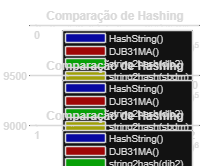

%%%%%%%%%%%%%%%%%% 1e5 %%%%%%%%%%%%%%
figure;
subplot(3,1,1);

histo1 = histogram(cell2mat(hash_array),'BinLimits',[0,5e5], 'NumBins',100, FaceColor='blue');
hold on;
histo2 = histogram(cell2mat(hash_array_djb),'BinLimits',[0,5e5], 'NumBins',100, FaceColor='red');
histo3 = histogram(cell2mat(hash_array_str),'BinLimits',[0,5e5], 'NumBins',100, FaceColor='green');
histo4 = histogram(cell2mat(hash_array_str_sb),'BinLimits',[0,5e5], 'NumBins',100, FaceColor='yellow');

ylim([14400, inf]);
legend('HashString()', 'DJB31MA()', 'string2hash(djb2)', 'string2hash(sbdm)');
xlabel('Valor');
ylabel('Hashing');
title('Comparação de Hashing');
hold off;

%%%%%%%%%%%%%%%%%% 1e6 %%%%%%%%%%%%%%

subplot(3,1,2);

histo12 = histogram(cell2mat(hash_array),'BinLimits',[5e5,1e6], 'NumBins',100, FaceColor='blue');
hold on;
histo22 = histogram(cell2mat(hash_array_djb),'BinLimits',[5e5,1e6], 'NumBins',100, FaceColor='red');
histo32 = histogram(cell2mat(hash_array_str),'BinLimits',[5e5,1e6], 'NumBins',100, FaceColor='green');
histo42 = histogram(cell2mat(hash_array_str_sb),'BinLimits',[5e5,1e6], 'NumBins',100, FaceColor='yellow');

ylim([9400, inf]);
legend('HashString()', 'DJB31MA()', 'string2hash(djb2)', 'string2hash(sbdm)');
xlabel('Valor');
ylabel('Hashing');
title('Comparação de Hashing');
hold off;

%%%%%%%%%%%%%%%%%% 2e6 %%%%%%%%%%%%%%

subplot(3,1,3);

histo123 = histogram(cell2mat(hash_array),'BinLimits',[1e6,2e6], 'NumBins',100, FaceColor='blue');
hold on;
histo223 = histogram(cell2mat(hash_array_djb),'BinLimits',[1e6,2e6], 'NumBins',100, FaceColor='red');
histo323 = histogram(cell2mat(hash_array_str),'BinLimits',[1e6,2e6], 'NumBins',100, FaceColor='green');
histo423 = histogram(cell2mat(hash_array_str_sb),'BinLimits',[1e6,2e6], 'NumBins',100, FaceColor='yellow');

ylim([9000, inf]);
legend('HashString()', 'DJB31MA()', 'string2hash(djb2)', 'string2hash(sbdm)');
xlabel('Valor');
ylabel('Hashing');
title('Comparação de Hashing');
hold off;

## Comparação do tempo

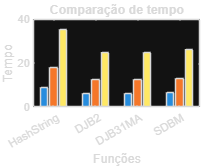

data = [tempo_hashString;tempo_DJB2;tempo_DJB31MA;tempo_SDBM];
figure;
bar(data,'grouped');
xlabel('Funções');
ylabel('Tempo');
title('Comparação de tempo');
set(gca, 'XTickLabel', {'HashString','DJB2','DJB31MA','SDBM'});

## Comparação de colisões

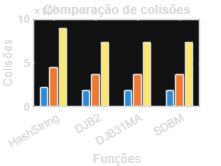

coli_data = [col_array_hash;col_array_djb2;col_array_DJB31MA;col_array_sdbm];
figure;
bar(coli_data,'grouped');
xlabel('Funções');
ylabel('Colisões');
title('Comparação de colisões');
set(gca, 'XTickLabel', {'HashString','DJB2','DJB31MA','SDBM'});

## Comparação de máximas atribuições

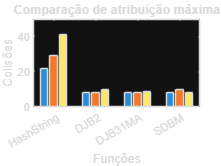

max_data = [max_hash;max_djb2;max_DJB31MA;max_sdbm];
figure;
bar(max_data,'grouped');
xlabel('Funções');
ylabel('Colisões');
title('Comparação de atribuição máxima');
set(gca, 'XTickLabel', {'HashString','DJB2','DJB31MA','SDBM'});